# **Test v3 (Simple code)**

Edmundo A. Miranda (12-11-2022)

**Description**: Processing data in .mat format from **SiemensProcData_EMZ** *folder*

## ATHS & LOADING DATA 

clear all, clc, close all

%%%% PATHS %%%%
% cd('D:\emirandaz\');

% HECTOR CODE %
% addpath('D:\emirandaz\codigo\')
% addpath('D:\emirandaz\codigo\entregable-2-fondecyt\')
% addpath('D:\emirandaz\codigo\entregable-2-fondecyt\est_methods\')
% addpath('D:\emirandaz\codigo\entregable-2-fondecyt\utils\')

% EMZ ADAPTED DATA (MATLAB FORMAT)
% addpath('D:\emirandaz\Data-UIUC\')
% addpath('D:\emirandaz\Data-UIUC\SiemensProcData_EMZ\')
% addpath('D:\emirandaz\Data-UIUC\Test_EMZ\')
% addpath('D:\emirandaz\Data-UIUC\SiemensProcData_EMZ\Operator_AH\')
% addpath('D:\emirandaz\Data-UIUC\SiemensProcData_EMZ\Operator_ZT\')


addpath('..\Data-UIUC\')
addpath('..\Data-UIUC\SiemensProcData_EMZ\')
addpath('..\Data-UIUC\Test_EMZ\')
addpath('..\Data-UIUC\SiemensProcData_EMZ\Operator_AH\')
addpath('..\Data-UIUC\SiemensProcData_EMZ\Operator_ZT\')
addpath('..\Data-UIUC\Test_EMZ\')


% pathDataUIUC = [pwd, '\Data-UIUC\'];

pathDataUIUC = [pwd,'\'];
pathEMZdata = [pathDataUIUC,'SiemensProcData_EMZ'];


Son 2 phantoms (P20 y P22) escaneados a tres frecuencias (2.5, 4, 5.5 MHz) c/u. Puesto a que son los mismos settings entonces estimar P20 y usar el P22 como referencia ambos a la misma frec y mismo operator, y así reciprocamente.

## SPECS - READ DATA (SAM & REF)

operator = 'AH'; % CHANGEABLE

numPhantomSam = 20;

numPhantomRef = 22;

freqValue = 4.0; % 2.5, 4, 5.5 [MHZ]

phantomSamInfo = selectPhantom(operator, numPhantomSam, freqValue);
phantomRefInfo =  selectPhantom(operator, numPhantomRef, freqValue);

%%%%%%%%%%%%%%%%%%%%% RESUMEN %%%%%%%%%%%%%%%%%%%%%
% fprintf('Data resumen\n');

sam = {phantomSamInfo.operator, ['P', num2str(phantomSamInfo.numPhantom)], ...
    phantomSamInfo.freqChar, phantomSamInfo.numCase};

ref = {phantomRefInfo.operator, ['P', num2str(phantomRefInfo.numPhantom)], ...
    phantomRefInfo.freqChar, phantomRefInfo.numCase};

T = table(sam',ref', ...
    'VariableNames', {'SAMPLE','REFERENCE'}, ...
    'RowName',{'Operator','N° Phantom', 'Freq [MHz]', 'N° Case'}); 

disp(T)

                    SAMPLE      REFERENCE 
                  __________    __________

    Operator      {'AH'    }    {'AH'    }
    N° Phantom    {'P20'   }    {'P22'   }
    Freq [MHz]    {'4.0'   }    {'4.0'   }
    N° Case       {[130724]}    {[134447]}



clear T sam ref

%%%%%%%%%%%%%%%%%%%%% FOLDER NAME %%%%%%%%%%%%%%%%%%%%%

folderNameSam =  ['P', num2str(phantomSamInfo.numPhantom), '_', ...
    'F', phantomSamInfo.freqChar, 'MHz_', ...
     num2str(phantomSamInfo.numCase)]

folderNameSam = 'P20_F4.0MHz_130724'


folderNameRef =  ['P', num2str(phantomRefInfo.numPhantom), '_', ...
    'F', phantomRefInfo.freqChar, 'MHz_', ...
     num2str(phantomRefInfo.numCase)]

folderNameRef = 'P22_F4.0MHz_134447'


%%%%%%%%%%%%%%%%%%%%% READ FOLDER %%%%%%%%%%%%%%%%%%%%%

pathDataSam = [pathEMZdata, '/Operator_', phantomSamInfo.operator, ...
    '/', folderNameSam];
pathDataRef = [pathEMZdata, '/Operator_', phantomRefInfo.operator, ...
    '/', folderNameRef];

SAM = load([pathDataSam, '/dataSiemens.mat'])

SAM = struct with fields:
       RF_data: [9348×280 double]
         axial: [1×9348 double]
       lateral: [1×280 double]
    parameters: [1×1 struct]


REF = load([pathDataRef, '/dataSiemens.mat'])

REF = struct with fields:
       RF_data: [9348×280 double]
         axial: [1×9348 double]
       lateral: [1×280 double]
    parameters: [1×1 struct]


## B MODE PLOTS

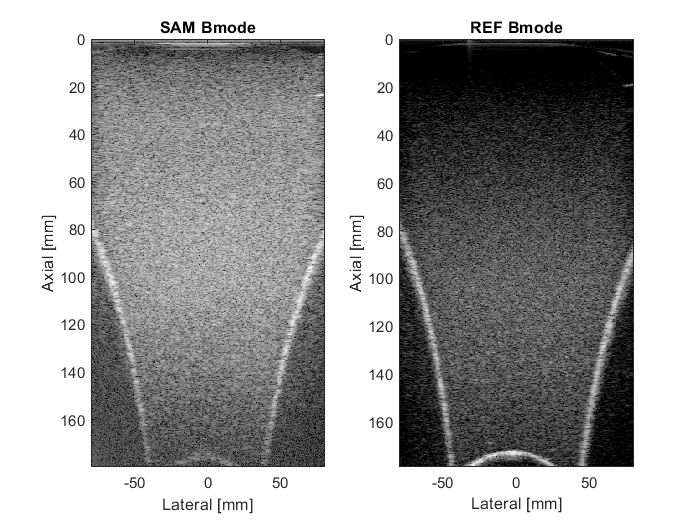

Bmode_SAM = Bmode(SAM.RF_data); % SAM.axial y SAM.lateral in mm
Bmode_REF = Bmode(REF.RF_data); % REF.axial y REF.lateral in mm

figure,
subplot 121,
imagesc(SAM.lateral, SAM.axial, Bmode_SAM), colormap("gray")
title('SAM Bmode'), xlabel('Lateral [mm]'), ylabel('Axial [mm]');
set(gca, 'clim', [-60 0])
subplot 122,
imagesc(REF.lateral, REF.axial, Bmode_REF), colormap("gray")
title('REF Bmode'), xlabel('Lateral [mm]'), ylabel('Axial [mm]');
set(gca, 'clim', [-60 0])

## 2. ACS & BSC MEASUREMENTS

### 2.1. ACS SAMPLE and REFERENCE

%Bande frequentiel de calcul
P = 2^10; % number of points (powers of 2)
fct = 1e6; % for MHz
BW = [1.5 6];
fs = 40E6; % 40 MHz
Np2dB = 8.6858; % To convert Np to dB
% fun_Np2dB = @(x) 8.6858*x;
% fun_dB2Np = @(x) x/8.6858;

Xfreq = (0 : (P/2-1))*fs/(P*fct);    % [MHz]                           
lambda_sam = SAM.parameters.c/(mean([BW(1) BW(2)])*fct); % [wavelength]
lambda_ref = REF.parameters.c/(mean([BW(1) BW(2)])*fct); % [wavelength]

fprintf('\nCalculation bandwidth SAMPLE:\nBW = %g - %g MHz, Fc = %g MHz\nwavelength (wl) = %g mm\n', BW(1), BW(2), mean([BW(1) BW(2)]), lambda_sam*1e3);


Calculation bandwidth SAMPLE:
BW = 1.5 - 6 MHz, Fc = 3.75 MHz
wavelength (wl) = 0.410667 mm


fprintf('\nCalculation bandwidth REFERENCE:\nBW = %g - %g MHz, Fc = %g MHz\nwavelength (wl) = %g mm\n', BW(1), BW(2), mean([BW(1) BW(2)]), lambda_ref*1e3);


Calculation bandwidth REFERENCE:
BW = 1.5 - 6 MHz, Fc = 3.75 MHz
wavelength (wl) = 0.408 mm



Fi = find(Xfreq >= BW(1));
Ff = find(Xfreq >= BW(2));
band_ind = Fi(1) : Ff(1);            % [sample]
band = band_ind*fs/(fct*P);          % [MHz]
band_k = 2*pi*band*fct/SAM.parameters.c;   % [rad/s]

% Choice of window type
window_type = 2; % 1. Hanning, 2. Tuckey-0.25, 3. Hamming, 4. Chebyshev
        
% Transmisson coefficient for Saran layer
% TT = transmission_saran(band);

% Attenuation of the sample phantom

ATT_sam = attenuation_phantoms_Np(band, phantomSamInfo.numPhantom); % [Np/cm]
[alpha_sam, ~, y_lin_sam, ~] = fit_linear(band, Np2dB*ATT_sam', 2);  % [dB/cm.MHz]
        
fprintf('ACS sample = %.4f dB/cm.Hz\n', alpha_sam);

ACS sample = 0.7047 dB/cm.Hz


% Attenuation of the reference phantom
ATT_ref = attenuation_phantoms_Np(band, phantomRefInfo.numPhantom); % [Np/cm]
[alpha_ref, ~, y_lin_ref, ~] = fit_linear(band, Np2dB*ATT_ref', 2); % [dB/cm.MHz]

fprintf('ACS reference = %.4f dB/cm.Hz\n', alpha_ref);

ACS reference = 0.3129 dB/cm.Hz


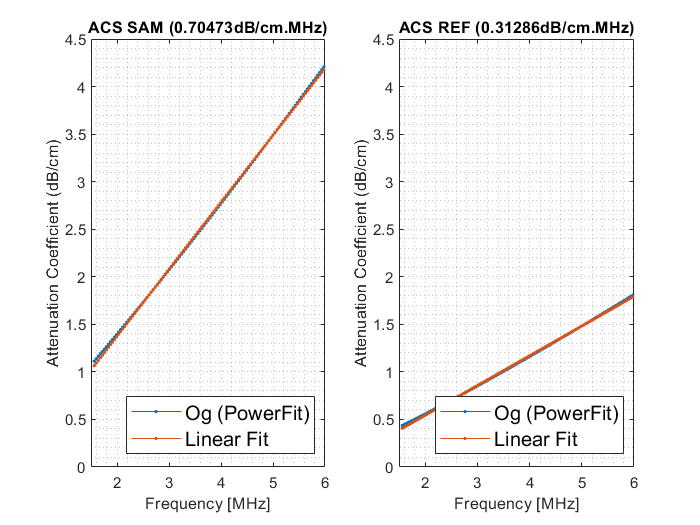

% PLOTS
figure,

subplot 121,
plot(band, Np2dB*ATT_sam', '.-'), hold on;
plot(band, y_lin_sam, '.-'), grid minor, hold off;
xlabel('Frequency [MHz]'), ylabel('Attenuation Coefficient (dB/cm)'),
title(['ACS SAM (', num2str(alpha_sam), 'dB/cm.MHz)']), ylim([0 4.5]), xlim([1.5 6]);
legend('Og (PowerFit)', 'Linear Fit', 'Location', 'SouthEast', 'Fontsize', 12);

subplot 122,
plot(band, Np2dB*ATT_ref', '.-'), hold on;
plot(band, y_lin_ref, '.-'), grid minor, hold off;
xlabel('Frequency [MHz]'), ylabel('Attenuation Coefficient (dB/cm)'),
title(['ACS REF (', num2str(alpha_ref), 'dB/cm.MHz)']), ylim([0 4.5]), xlim([1.5 6]);
legend('Og (PowerFit)', 'Linear Fit', 'Location', 'SouthEast', 'Fontsize', 12);

### 2.2. BSC SAMPLE and REFERENCE

fileNameBSC_sam = ['BSC_vs_freq_P', num2str(phantomSamInfo.numPhantom),'.txt']

fileNameBSC_sam = 'BSC_vs_freq_P20.txt'

fileNameBSC_ref = ['BSC_vs_freq_P', num2str(phantomRefInfo.numPhantom),'.txt']

fileNameBSC_ref = 'BSC_vs_freq_P22.txt'

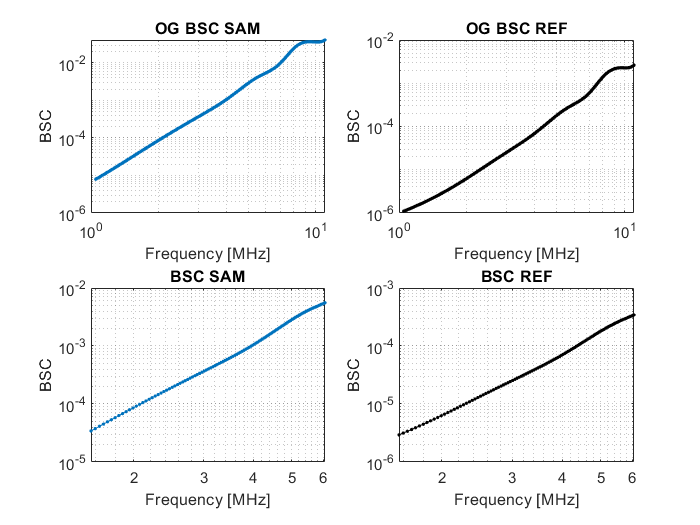

file_BSCsam = readmatrix(fileNameBSC_sam); % Freq, BSC
file_BSCref = readmatrix(fileNameBSC_ref); % Freq, BSC

% freqs | bsc
% BSC_sam = interp1(freqs, bsc, band);
BSC_sam = interp1(file_BSCsam(:,1), file_BSCsam(:,2), band);
BSC_ref = interp1(file_BSCref(:,1), file_BSCref(:,2), band);
% clear file_BSCref file_BSCsam

% PLOTS
figure,
subplot 221,
loglog(file_BSCsam(:,1), file_BSCsam(:,2), '.-'), grid minor;
xlabel('Frequency [MHz]'), ylabel('BSC'),
title('OG BSC SAM')

subplot 222,
loglog(file_BSCref(:,1), file_BSCref(:,2), 'k.-'), grid minor;
xlabel('Frequency [MHz]'), ylabel('BSC'),
title('OG BSC REF')

subplot 223,
loglog(band, BSC_sam, '.-'), grid minor;
xlabel('Frequency [MHz]'), ylabel('BSC'),
title('BSC SAM')

subplot 224,
loglog(band, BSC_ref, 'k.-'), grid minor;
xlabel('Frequency [MHz]'), ylabel('BSC'),
title('BSC REF')

### **REF PHANTOM METHOD (RPM)**


%%%% FORMATING SAMPLE TO DATA_RPM %%%%
DATA_RPM.RF = SAM.RF_data; 
DATA_RPM.x = SAM.lateral/1e3; % was in [mm] to [m]
DATA_RPM.z = SAM.axial/1e3; % was in [mm] to [m]
DATA_RPM.c = SAM.parameters.c; % [m/s]
% DATA.Bmode = Bmode(SAM.RF_data);
DATA_RPM.Bmode = Bmode_SAM;
DATA_RPM.fs = fs;

%%%% FORMATING REFERENCE TO REF_RPM %%%%
REF_RPM.RF = REF.RF_data; 
REF_RPM.x = REF.lateral/1e3; % was in [mm] to [m]
REF_RPM.z = REF.axial/1e3; % was in [mm] to [m]
REF_RPM.c = REF.parameters.c; % [m/s]
REF_RPM.fs = fs;

%%%% FORMATING PARAMETERS %%%%
pars.BW = BW;
pars.P = P;
pars.nb_lambda_axial = 20;
pars.overlap_axial = 0.8;
pars.overlap_lateral = 0.8;
pars.REF_num = phantomRefInfo.numPhantom;
pars.BSC_ref = BSC_ref;

pars.z_ini = 20e-3; % in [m]
pars.z_end = 80e-3; % in [m]

pars.x_ini = -50e-3; %in [m]
pars.x_end = 50e-3; %in [m]



Calculation bandwidth:
BW = 1.5 - 6 MHz, Fc = 3.75 MHz
wavelength (wl) = 0.408 mm

Axial gate length = 20 wl = 8.16 mm = 424 samp.
Number of axial region = 32

Lateral gate length = 20.0 wl = 8.16 mm = 16 lines
Number of lateral region = 39


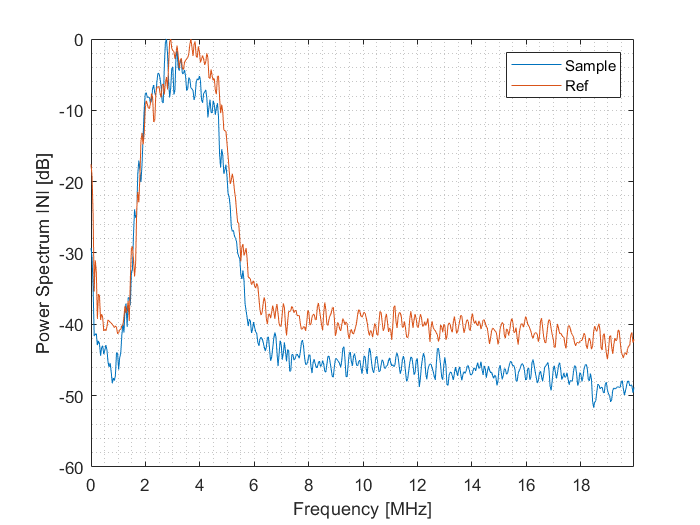

Reference to non-existent field 'SAM_num'.

Error in caculateBSC_RPM (line 248)
                ATT_sam = attenuation_phantoms_Np(band, pars.SAM_num); % [Np/cm]

[BSC] = caculateBSC_RPM(DATA_RPM, REF_RPM, pars, Bmode_SAM)